clear all
close all
clc

% Initial values for d1, d2, d3, d4
d0 = [3.1623   1    1.0000    1];

% Define lower and upper bounds, if any
lb = [0,0,0,0];  % Lower bounds (set if applicable)
ub = [];  % Upper bounds (set if applicable)

% Define any linear constraints (set as empty if not applicable)
A = []; b = [];
Aeq = []; beq = [];

% Define options for fmincon
options = optimoptions('fmincon','MaxIterations', 100, ...
    'MaxFunctionEvaluations', 200, ...
    'Display', 'iter'); % 'sqp' is a popular algorithm for constrained problems

% Run fmincon
[d_opt, fval] = fmincon(@(d) dataGenerator2(d), d0, A, b, Aeq, beq, lb, ub, [], options);

% Display the optimized parameters and the corresponding consensus error
disp(['Optimized d1: ', num2str(d_opt(1))]);
disp(['Optimized d2: ', num2str(d_opt(2))]);
disp(['Optimized d3: ', num2str(d_opt(3))]);
disp(['Optimized d4: ', num2str(d_opt(4))]);
disp(['Final consensus error: ', num2str(fval)]);


clear all
close all
clc

matFile = 'Results/Case2/gridSearchCompleteDesignResults.mat';
data = load(matFile);

pValRange = data.pValRange;
deltaCostCoefRange = data.deltaCostCoefRange;
gammaCostCoefRange = data.gammaCostCoefRange;
comCostLimitRange = data.comCostLimitRange;

minJ = inf;
for gIdx = 1:length(gammaCostCoefRange)
    for comIdx = 1:length(comCostLimitRange)
        for dIdx = 1:length(deltaCostCoefRange)
            for pIdx = 1:length(pValRange)
                d = [];
                d(1) = pValRange(pIdx);
                d(2) = deltaCostCoefRange(dIdx);
                d(3) = gammaCostCoefRange(gIdx);
                d(4) = comCostLimitRange(comIdx);
                if ~any(isnan(d))
                    d
                    J = dataGenerator2(d)
                    minJ
                    if J<minJ
                        minJ = J
                        bestD = d
                    end
                end
            end
        end
    end
end
bestD 
minJ

% d = [3.1623  0.0010  1.0000  0.1000]
d = [0.0316    1000    100    0.01]
dataGenerator2(d) % 29.97

minJ = dataGenerator2(d)
for p = 0.01:0.01:1
    d(1) = p;
    if ~any(isnan(d))
        d
        J = dataGenerator2(d)
        minJ
        if J<minJ
            minJ = J
            bestD = d
        end
    end
end
minJ
bestD

In this part, lets first store the initial networks under the four control strategies. Then, lets use them to run multiple iterations over different demand variations

clear all
close all
clc

rng(7)

caseNum = 2;

if caseNum == 1
    numOfChains = 2;            % Number of parallel chains
    numOfInventories = 3;       % Number of inventories in each chain
    matFile = 'Results/Case1/gridSearchCompleteDesignResults.mat';
elseif caseNum == 2
    numOfChains = 3;            % Number of parallel chains
    numOfInventories = 4;       % Number of inventories in each chain
    matFile = 'Results/Case2/gridSearchCompleteDesignResults.mat';
elseif caseNum == 3
    numOfChains = 4;            % Number of parallel chains
    numOfInventories = 5;       % Number of inventories in each chain
    matFile = 'Results/Case3/gridSearchCompleteDesignResults.mat';
end

% Create Network
netId = 1;               % Supply chain network ID
net = Network(netId, numOfChains, numOfInventories);

Started creating the supply chain network.
Started creating chain 1
Finished creating a chain...
Started creating chain 2
Finished creating a chain...
Started creating chain 3
Finished creating a chain...
Finished creating the supply chain network.


net.setInitialErrors();

tMax = 24*30 % 4 weeks

tMax = 720

saveMode = 3; % 1 FigSave, 2 vidSave, 3 display

d1 = 0;
d2 = -0; %-10
d3 = 1;
d4 = 0;
d5 = 1;
d6 = 1;
[pVal, deltaCostCoef, gammaCostCoef, comCostLimit] = net.findBestParameters(matFile,d1,d2,d3,d4,d5,d6) 

Error in c:
    0.2572   11.8655    0.0118       Inf    0.4036    0.1358

Best parameter combination found:
Minimum objective value: 0.81347
pVal: 0.1
deltaCostCoef: 316.2278
gammaCostCoef: 1000
comCostLimit: 0.0031623
LNorm: 1.3322
KNorm: 0.031596
gammaTilde: 210.3225
KLinks: 101
JCon: 24.5364
JTra: 44.4732


pVal = 0.1000

deltaCostCoef = 316.2278

gammaCostCoef = 1000

comCostLimit = 0.0032


d = [0.0316, 1000, 100, 0.01]

d = 1.0e+03 *

    0.0000    1.0000    0.1000    0.0000


pVal = d(1)

pVal = 0.0316

deltaCostCoef = d(2)

deltaCostCoef = 1000

gammaCostCoef = d(3) %100

gammaCostCoef = 100

comCostLimit = d(4)

comCostLimit = 0.0100


save(['tempNet',num2str(caseNum)])
netData.netNames{1} = 'Basic';
netData.nets{1} = net;
save('caseNum0.mat','caseNum','netData');

Local Steady State Control (LSSC): K = 0, L = 0

clear all
close all
clc

load('caseNum0.mat','caseNum','netData')
tagVal = 'Steady';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])

rng(7)

% Some arbitrarily designed local and global controllers:
for i = 1:numOfChains
    net.chains{i}.LLocal = 0*net.chains{i}.LLocal;
end
net.chains{1}.LLocal;
net.KGlobal = 0*net.KGlobal;
net.setAdjointMatrixAndNeighborsAndControllers();

netData.netNames{end+1} = 'LSSC';
netData.nets{end + 1} = net;
save('caseNum0.mat','caseNum','netData')

Local State Feedback Control (LSFC): K = 0

clear all
close all
clc

load('caseNum0.mat','caseNum','netData')
tagVal = 'NullGraph';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])

rng(7)

% Some arbitrarily designed local and global controllers:
for i = 1:numOfChains
    pVal = NaN;
    net.chains{i}.localControlDesign(pVal,deltaCostCoef);
end
net.chains{1}.LLocal

ans =    -0.5830   -0.6748   -0.7289   -0.5919   -0.6494   -0.6954   -0.6363   -0.7517   -0.8093   -0.8103   -0.8950   -0.9454   -1.0114   -0.6578   -0.7284   -0.8086
    0.0221   -0.3972   -0.3566   -0.3197    0.0306   -0.0829   -0.1987   -0.4431   -0.4352   -0.3967   -0.4312   -0.4841   -0.5175   -0.3559   -0.3816   -0.4490
   -0.1766   -0.0675   -0.3904   -0.3041   -0.1968   -0.2078   -0.2082   -0.0703   -0.1703   -0.4349   -0.4622   -0.4850   -0.4443   -0.3369   -0.3939   -0.4372
   -0.0982   -0.1325    0.0509   -0.2766   -0.1097   -0.1119   -0.1156   -0.1484   -0.1436    0.0628   -0.0524   -0.1363   -0.1750   -0.3083   -0.3264   -0.2845


net.KGlobal = 0*net.KGlobal;
net.setAdjointMatrixAndNeighborsAndControllers();

netData.netNames{end+1} = 'LSFC';
netData.nets{end + 1} = net;
save('caseNum0.mat','caseNum','netData')

Global control

clear all
close all
clc

load('caseNum0.mat','caseNum','netData')
tagVal = 'Steady';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])

rng(7)

% Some arbitrarily designed local and global controllers:
for i = 1:numOfChains
    net.chains{i}.LLocal = 0*net.chains{i}.LLocal;
end
net.globalConsensusControlDesign();
net.KGlobal

ans =     0.0002    0.0019   -0.0007    0.0002    0.0019   -0.0011   -0.0011   -0.0007   -0.0007   -0.0007    0.0019   -0.0011
    0.4109   -0.0472   -0.0342   -0.0391   -0.0472   -0.0311   -0.0311   -0.0342   -0.0342   -0.0342   -0.0472   -0.0311
   -0.0394    0.4027   -0.0345   -0.0394   -0.0473   -0.0305   -0.0305   -0.0345   -0.0345   -0.0345   -0.0473   -0.0305
   -0.0392   -0.0480    0.4158   -0.0392   -0.0480   -0.0303   -0.0303   -0.0342   -0.0342   -0.0342   -0.0480   -0.0303
    0.0002    0.0038   -0.0012    0.0002    0.0038   -0.0023   -0.0023   -0.0012   -0.0012   -0.0012    0.0038   -0.0023
   -0.0394   -0.0478   -0.0343   -0.0394    0.4022   -0.0302   -0.0302   -0.0343   -0.0343   -0.0343   -0.0478   -0.0302
   -0.0391   -0.0480   -0.0341   -0.0391   -0.0480    0.4196   -0.0304   -0.0341   -0.0341   -0.0341   -0.0480   -0.0304
   -0.0391   -0.0475   -0.0343   -0.0391   -0.0475   -0.0307    0.4193   -0.0343   -0.0343   -0.0343   -0.0475   -0.0307
    0.0003    0.0019   -0.

net.setAdjointMatrixAndNeighborsAndControllers();

netData.netNames{end+1} = 'GCC';
netData.nets{end + 1} = net;
save('caseNum0.mat','caseNum','netData')

Distributed Control with Hard Graph Constraints

clear all
close all
clc

load('caseNum0.mat','caseNum','netData')
tagVal = 'SoftGraph';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])
rng(7)

isSoft = 0;

totalStatusLocal = 1;
totalLNorm = 0;
for i = 1:1:net.numOfChains
    [statusLocal, ~, ~, LNormVal, ~, ~] = net.chains{i}.localControlDesign(pVal, deltaCostCoef);
    if ~statusLocal
        totalStatusLocal = 0;
        break;
    else
        totalLNorm = totalLNorm + LNormVal;
    end
end
totalStatusLocal

totalStatusLocal = 1

totalLNorm = totalLNorm / net.numOfChains

totalLNorm = 1.3341

% Global controller design
if totalStatusLocal
    [statusGlobal, gammaTildeVal, ~, ~, KNormVal] = net.globalControlDesign(gammaCostCoef,comCostLimit,isSoft)
end

statusGlobal = logical
   1


gammaTildeVal = 209.7839

KNormVal = 2.0287e-05

net.setAdjointMatrixAndNeighborsAndControllers(); % Load Graph, neighbors and controllers from KVal

netData.netNames{end+1} = 'DCC-C';
netData.nets{end + 1} = net;
save('caseNum0.mat','caseNum','netData')

Distributed Control with Soft Graph Constraints

clear all
close all
clc

load('caseNum0.mat','caseNum','netData')
tagVal = 'SoftGraph';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])
rng(7)

isSoft = 1;

totalStatusLocal = 1;
totalLNorm = 0;
for i = 1:1:net.numOfChains
    [statusLocal, ~, ~, LNormVal, ~, ~] = net.chains{i}.localControlDesign(pVal, deltaCostCoef);
    if ~statusLocal
        totalStatusLocal = 0;
        break;
    else
        totalLNorm = totalLNorm + LNormVal;
    end
end
totalStatusLocal

totalStatusLocal = 1

totalLNorm = totalLNorm / net.numOfChains

totalLNorm = 1.3341

% Global controller design
if totalStatusLocal
    [statusGlobal, gammaTildeVal, ~, ~, KNormVal] = net.globalControlDesign(gammaCostCoef,comCostLimit,isSoft)
end

statusGlobal = logical
   1


gammaTildeVal = 209.7839

KNormVal = 0.0737

net.setAdjointMatrixAndNeighborsAndControllers(); % Load Graph, neighbors and controllers from KVal

netData.netNames{end+1} = 'DCC-U';
netData.nets{end + 1} = net;
save('caseNum0.mat','caseNum','netData')
save('caseNum1.mat','caseNum','netData')

 Now we are ready to evaluate the controllers 

clear all
close all
clc

load('caseNum1.mat','caseNum','netData')

numOfRealizations = 1000;
tMax = 24*30;
numOfCases = 5;

sumConError = zeros(numOfCases,tMax);
sumTraError = zeros(numOfCases,tMax);
sumCumConError = zeros(numOfCases,tMax);
sumCumTraError = zeros(numOfCases,tMax);

for i = 1:1:numOfRealizations
    
    if mod(i,20)==0
        disp(i)
    end

    load('caseNum0.mat','netData');
    rng(i)
    seed = randi([1,1000*numOfRealizations]);
    for k = 1:numOfCases
        rng(seed);
        net = netData.nets{k+1};
        net.randomizeInitialState();
        for t = 1:1:tMax
            net.update();  % Update the entire network
        end
        net.computeErrorHistory();
        sumConError(k,:) = sumConError(k,:) + net.consensusErrorHistory;
        sumTraError(k,:) = sumTraError(k,:) + net.trackingErrorHistory;
        sumCumConError(k,:) = sumCumConError(k,:) + net.cumMeanAbsConErrorHistory;
        sumCumTraError(k,:) = sumCumTraError(k,:) + net.cumMeanAbsTraErrorHistory;
    end 
end

    20

    40

    60

    80

   100

   120

   140

   160

   180

   200

   220

   240

   260

   280

   300

   320

   340

   360

   380

   400

   420

   440

   460

   480

   500

   520

   540

   560

   580

   600

   620

   640

   660

   680

   700

   720

   740

   760

   780

   800

   820

   840

   860

   880

   900

   920

   940

   960

   980

        1000



avgConError = sumConError/numOfRealizations;
avgTraError = sumTraError/numOfRealizations;
avgCumConError = sumCumConError/numOfRealizations;
avgCumTraError = sumCumTraError/numOfRealizations;

netData.avgConError = avgConError;
netData.avgTraError = avgTraError;
netData.avgCumConError = avgCumConError;
netData.avgCumTraError = avgCumTraError;

save('caseNum1.mat','caseNum','netData')
save('caseNum2.mat','caseNum','netData')

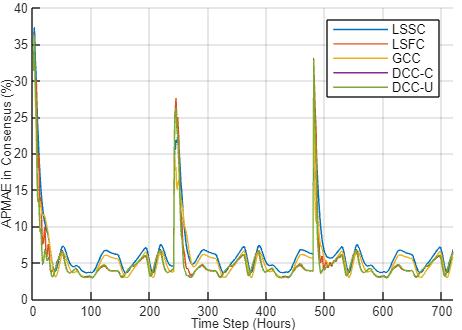

Figure saved as Results\PaperFigures\AvgConPerfCase2.png and Results\PaperFigures\AvgConPerfCase2.fig


clear all
close all
clc

load('caseNum2.mat','caseNum','netData')
avgConError = netData.avgConError;
avgTraError = netData.avgTraError;
avgCumConError = netData.avgCumConError;
avgCumTraError = netData.avgCumTraError;

tMax = 24*30;
numOfCases = 5;
net = netData.nets{1};
figNum = 1;
figure(figNum);
hold on; grid on; axis tight;
for k = 1:numOfCases
    plot(1:tMax, avgConError(k,:), '-', 'LineWidth', 0.8, 'DisplayName', netData.netNames{k+1});
end
axis([0,tMax,0,40])
xlabel('Time Step (Hours)');
ylabel('APMAE in Consensus (%)');
legend('Location', 'northeast');

figWidth = 3.5; figHeight = 2.5; fontSize = 7;
fileName = ['AvgConPerfCase',num2str(caseNum)];
net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);

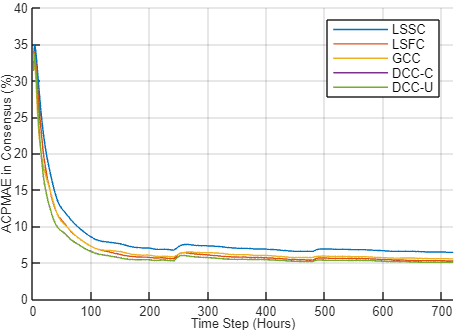

Figure saved as Results\PaperFigures\AvgCumConPerfCase2.png and Results\PaperFigures\AvgCumConPerfCase2.fig




figNum = figNum + 1;
figure(figNum);
hold on; grid on; axis tight;
for k = 1:5
    plot(1:tMax, avgCumConError(k,:), '-', 'LineWidth', 0.8,  'DisplayName', netData.netNames{k+1});
    % title(sprintf('Performance Metrics at Time Step %d', t)); 
end
axis([0,tMax,0,40])
xlabel('Time Step (Hours)');
ylabel('ACPMAE in Consensus (%)');
legend('Location', 'northeast'); 

figWidth = 3.5; figHeight = 2.5; fontSize = 7;
fileName = ['AvgCumConPerfCase',num2str(caseNum)];
net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);


avgCumConError(:,end)

ans =     6.4318
    5.2557
    5.5322
    5.0702
    5.0589



% figNum = figNum + 1;
% figure(figNum);
% hold on; grid on; axis tight;
% for k = 1:4
%     plot(1:tMax, avgTraError(k,:), '-', 'LineWidth', 0.8,  'DisplayName', netData.netNames{k+1});
% end
% axis([0,tMax,0,80])
% xlabel('Time Step (Hours)');
% ylabel('Mean Per. Abs. Tracking Error (%)');
% legend('Location', 'northeast'); 
% 
% figWidth = 3.5; figHeight = 2.5; fontSize = 7;
% fileName = ['AvgTraPerfCase',num2str(caseNum)];
% net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);